# Ezan Khan, Nick Lin, Peter Zhao

# Lab Section C3

# EK125 Final Project

## Article Synopsis

	When working with data, biases can occur when certain elements of the dataset are disproportionately weighed. The use of biased datasets in machine learning models produces skewed outcomes, which can lead to inaccurate conclusions and predictions. One such bias prevalent in machine learning is **systemic bias**, which occurs when certain social groups are favored while others are undervalued. There is also **automation bias**, which occurs when artificial intelligence-based recommendations are used before verifying the accuracy of that information. 

        **Selection bias** occurs in data sets that aren’t properly randomized. Similarly, when there aren’t enough data points or the data isn’t representative of the general population, you have **sample bias**. For example, if your training data only includes female nurses, the system may conclude that all nurses are females. Often regarded as the most common bias when working with data, **reporting bias** is the inclusion of a tiny subset of results in a machine learning analysis. One type of reporting bias is **publication bias**, an example of which is if a machine learning model was only done with positive findings rather than all findings.

	**Overgeneralization bias** takes place when reports extrapolate one event to all future events. A more complex bias is **group attribution bias**, which is a tendency to generalize what is true of one individual to an entire group to which they belong. Group attribution biases can be broken down into **in-group bias** (when you give preference to your own group) and **out-group bias** (when you stereotype members of groups you aren’t a part of). A more common bias is **implicit bias**, which takes place when we make assumptions based on our personal experiences. Similarly, if we try to confirm our own biases and expectations, we get **confirmation bias**. An example of confirmation bias is a person continuously testing their machine learning model until they get the results that support their hypothesis or expectations.

	Along with biases, **overfitting** and **underfitting** the data can lead to inaccurate results. In machine learning, overfitting happens when a model is trained with too much data, causing it to start learning from the noise and inaccurate data entries in the data set. In contrast, underfitting the data occurs when a machine learning model fails to capture the underlying trend of the data because the model is too simple. 

        Another way of looking at bias is the difference between the prediction of a model and the correct value you are trying to predict. Biased models are too simplified and skew their results. **Variance** is the variability in the model prediction. It contrasts biased models in that high variance models prioritize training data too much and doesn’t generalize data it hasn’t seen before. Although this leads to better results on **training data** (the subset of original data that is used to train the machine learning model), it causes high error rates on **test data** (data used to check the accuracy of the model). Therefore, all machine learning models must make a tradeoff between bias and variance, with the best models being the ones that can strike the perfect balance between the two.

        Having talked about all the ways biases, improper fitting, and variance can lead to inaccurate machine learning models, there is one solution: **synthetic data**. Synthetic data is data generated by computer simulations or algorithms and serves as an alternative to real-world data. Although the quality of raw synthetic data depends on the quality of raw real data, synthetic data can help address bias. In fact, the use of synthetic data has been an emerging solution to issues such as when there isn’t enough available data, when it is too costly to acquire the data, or if there isn’t consent for the real data to be used in machine learning projects. Currently, it seems that synthetic data is the future of AI and machine learning models, with some experts estimating that synthetic data will soon overshadow real data in many existing AI models.

**References**

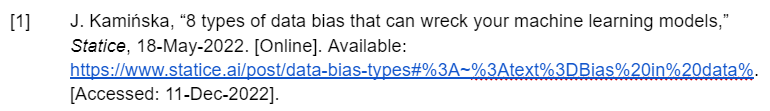

## Project Proposal

        Everyday our oceans become polluted with garbage, plastics, metals, and waste oils. This pollution has disastrous consequences, for both marine life and humanity. Firstly, marine life is dying out as a result of modern ocean pollution. In cases where certain fish species aren’t dying out, they’re consuming the plastics being dumped in the sea. When humans consume these fish, they’re also consuming the microplastics residing in the fish bodies. 

        Along with the quantity and quality of fish species getting worse due to our pollution habits, the livelihoods of many people are at stake. Fishing is a popular job for those residing near water or those in developing countries. Consequently, if the amount of fish in the sea starts decreasing, the jobs of tens of millions of fishermen across the world will be in jeopardy. As such, if our pollution habits continue, marine life will continue to die out, the quality of seafood will worsen, and millions of people across the world will lose their jobs.

        To combat this issue, we are going to identify the areas across the world that will be most populated with pollution in the future through the use of the Regression Learner. Additionally, we are going to identify the specific type of pollution that will become most prominent in the future through the use of the Classification Learner.  We will be using the **pollution density data set** for the Regression Learner and the **pollution type data set** for the Classification learner. Both data sets can be found with the links below.

Pollution density data file: [https://experience.arcgis.com/experience/b296879cc1984fda833a8acc93e31476](https://experience.arcgis.com/experience/b296879cc1984fda833a8acc93e31476) 

Pollution type data file: [https://pacificdata.org/data/dataset/marine-pollutionb7c085de-2247-4d9a-bb01-6aef1fbe25a2/resource/dad7608d-d947-4657-9c82-51477d98d7bb](https://pacificdata.org/data/dataset/marine-pollutionb7c085de-2247-4d9a-bb01-6aef1fbe25a2/resource/dad7608d-d947-4657-9c82-51477d98d7bb) 

## Import the Data (pollution_density.csv)

Below we are importing the data from our pollution_density csv file.

density_data = readtable('pollution_density.csv','PreserveVariableNames', true);

## Scrub the Data (pollution_density.csv)

For this data set, only the dates, plastic density, density class, and geocoordinates were needed and eveything else was scrubbed. Density Class and Ocean table variables are of the incorrect type and thus corrected to the corresponding types. We decided to keep all the years of data in the data file to better assess the density changes over the past few decades.

% scrubbing unnesscary data
density_data = removevars(density_data,{'Long Reference','Short Reference', ...
    'NCEI Accession Link', 'NCEI Accession Number','Regions','SubRegions', ...
    'Density Class Range','Keywords','Organization','DOI','Sampling Method', ...
    'Unit','x','y'});
% scrbbing unnesscary columns from the table
density_data.('Density Class') = categorical(density_data.('Density Class'));
% changing Density Class from 'cell' to 'categorical'
% which makes the geobubble figures possible
density_data.Oceans = string(density_data.Oceans);
% changing Oceans from 'cell' to 'string' for geobubble
head(density_data)

ans = 8×7 table
    FID       Date       Latitude    Longitude         Oceans         Microplastics Measurement (density)               Density Class            
    ___    __________    ________    _________    ________________    ___________________________________    ____________________________________

     1     10/31/1992     18.83       -59.35      "Atlantic Ocean"                  0.00432                  Low : 0.0005-0.005 pieces/m³        
     2     10/31/1992     18.83       -59.35      "Atlantic Ocean"                 0.034556                  Medium : 0.005-1 pieces/m³          
     3     11/01/1992      17.8       -59.43      "Atlantic Ocean"                  0.00864                  Medium : 0.005-1 pieces/m³          
     4     11/0

tail(density_data)

ans = 8×7 table
     FID        Date       Latitude    Longitude        Oceans         Microplastics Measurement (density)               Density Class            
    _____    __________    ________    _________    _______________    ___________________________________    ____________________________________

    10692    11/02/1972     34.95       -139.02     "Pacific Ocean"                       0                   Very Low: Less than 0.0005 pieces/m³
    10693    10/22/1972     38.98       -133.02     "Pacific Ocean"                   0.007                   Medium : 0.005-1 pieces/m³          
    10694    10/22/1972        39          -135     "Pacific Ocean"                    0.06                   Medium : 0.005-1 pieces/m³          
    10695 

% this mark the 5-year intervals that will be analyzed
stamps = 1978:5:2018;

## Exploratory Data Analysis (pollution_density.csv)

Since the focus of this data set is on plastic densities, we decided to look at the change in plastic densities across time. We partitioned the multi-decade data set into eight, five-year intervals to analyze the changes in plastic densities over 40 years. Most of the exploratory data analysis is contained within one for-loop. This for-loop splits the data into 5 year intervals, making discernable patterns clearer. Within this loop, eight geobubbles are generated, along with a structure of mean, median, and mode of plastic densities for each corresponding interval divided into the geographical territories of: the world, Atlantic ocean, and Pacific ocean. Outside the for-loop are matrices that store the values from the structure. Mode has been excluded in our output as the value is the same every time (0). The information on the matrices are finally plotted in order to measure plastic density change over the years.

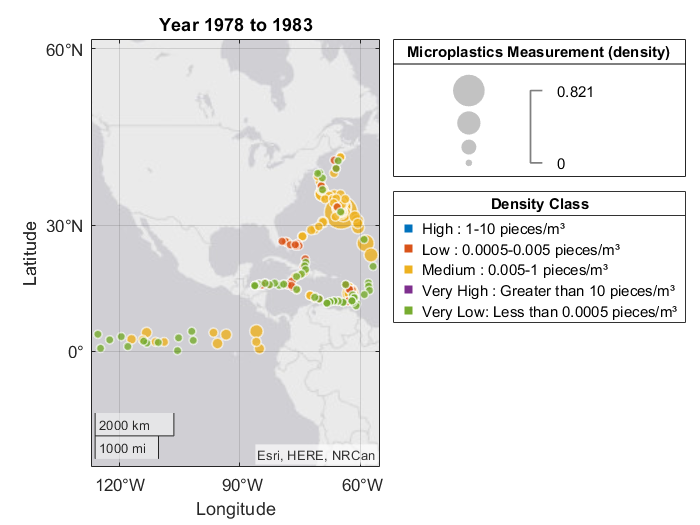

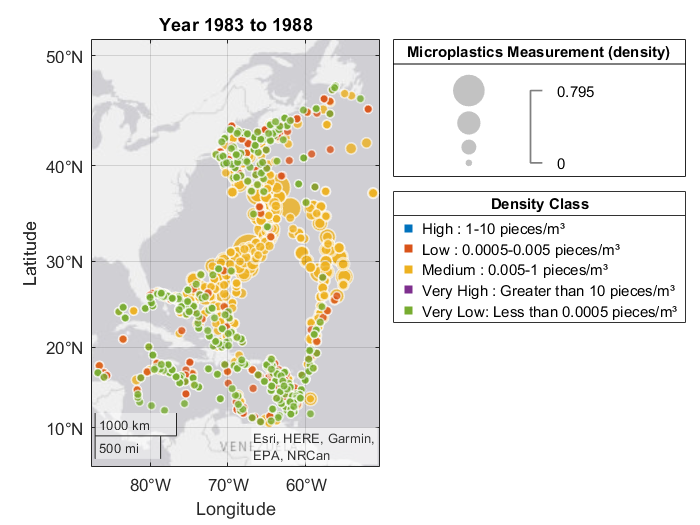

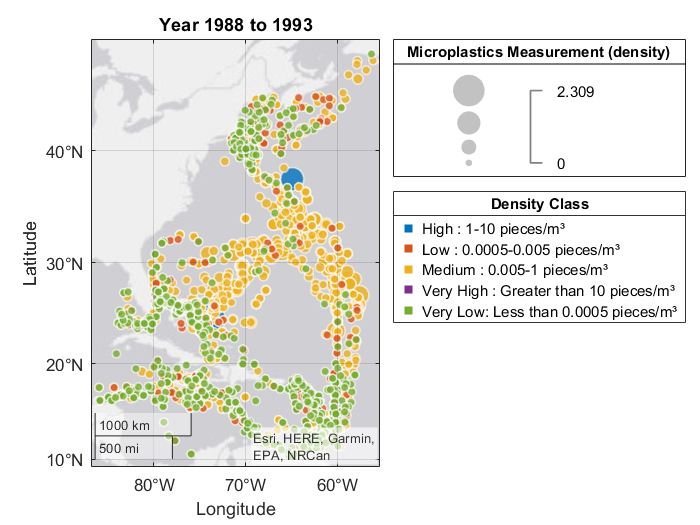

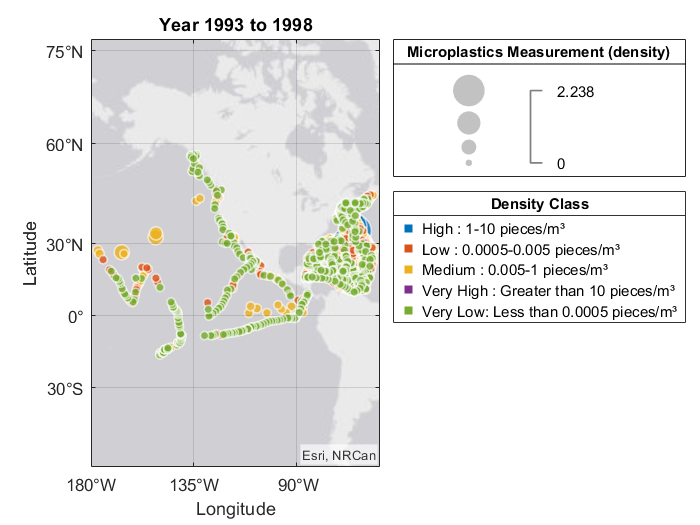

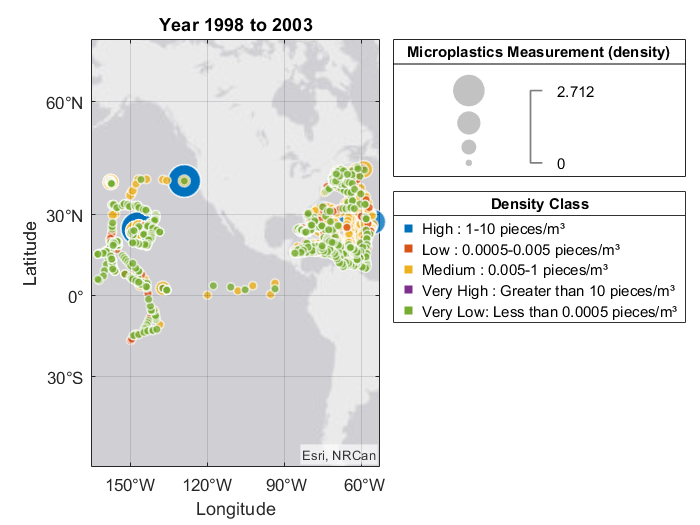

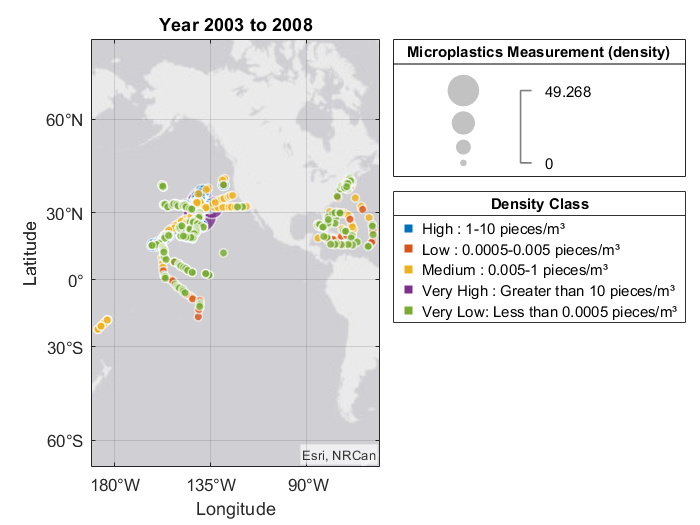

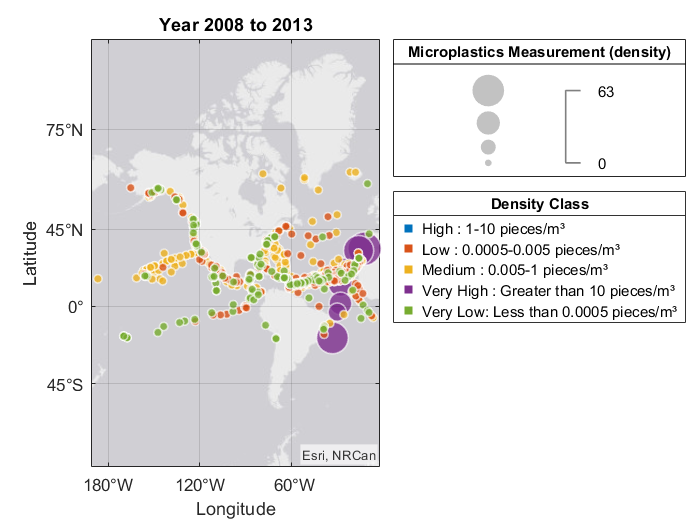

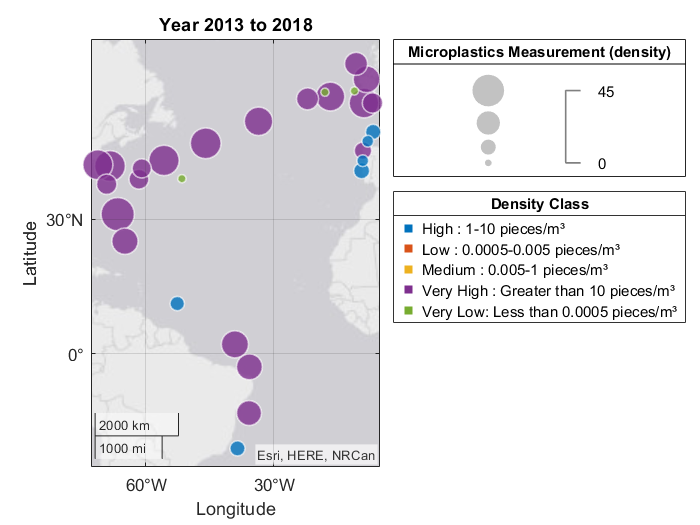

for i = 2:length(stamps)
    density_data_temp = density_data(density_data.Date < datetime(stamps(i)+5,01,01) & ...
        density_data.Date > datetime(stamps(i),01,01), :);

    % geobubble maps of microplastic densities classified on density levels
    figure(i);
    geobubble(density_data_temp,'Latitude','Longitude', ...
    'SizeVariable','Microplastics Measurement (density)','ColorVariable','Density Class')
    
    % years are printed with sprintf to reference the information
    % from our scrubbed data sets
    realTitle = sprintf('Year %d to %d',stamps(i-1),stamps(i));
    title(realTitle)

    % split density_data into atlantic and pacific portions
    density_atlantic =  density_data_temp(density_data_temp.Oceans == 'Atlantic Ocean', :);
    density_pacific =  density_data_temp(density_data_temp.Oceans == 'Pacific Ocean', :);

    density_stats(i-1) = struct('Year',stamps(i), ...
        'World',struct('Mean',mean(density_data_temp.('Microplastics Measurement (density)')),...
        'Median',median(density_data_temp.('Microplastics Measurement (density)')),...
        'Mode',mode(density_data_temp.('Microplastics Measurement (density)'))),...
        'Atlantic',struct('Mean',mean(density_atlantic.('Microplastics Measurement (density)')),...
        'Median',median(density_atlantic.('Microplastics Measurement (density)')),...
        'Mode',mode(density_atlantic.('Microplastics Measurement (density)'))),...
        'Pacific',struct('Mean',mean(density_pacific.('Microplastics Measurement (density)')),...
        'Median',median(density_pacific.('Microplastics Measurement (density)')),...
        'Mode',mode(density_pacific.('Microplastics Measurement (density)'))));
end

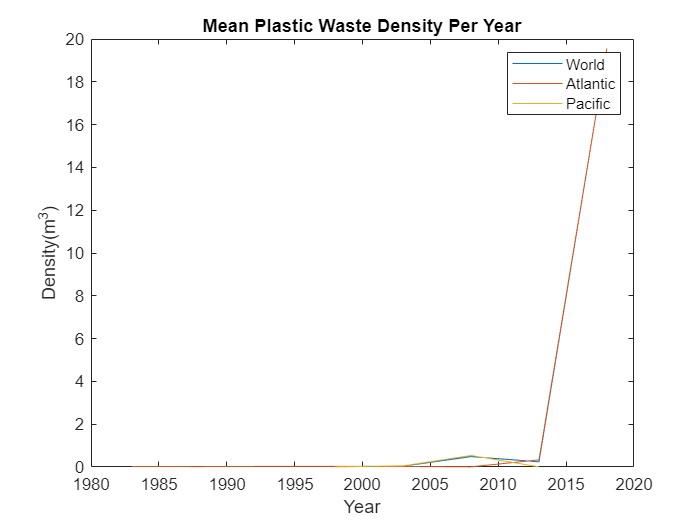

% creates a structure of means and median for 
% world, Atlantic, and Pacific microplastic densities
% mode has been excluded as all values are 0 
% or super small concentrations
means = zeros(8,3);
medians = zeros(8,3);

% the structure values are fed into 2 matrices for easier graphing
for i = 1:(length(stamps)-1)
    means(i,1) = density_stats(i).World.Mean;
    means(i,2) = density_stats(i).Atlantic.Mean;
    means(i,3) = density_stats(i).Pacific.Mean;
    medians(i,1) = density_stats(i).World.Median;
    medians(i,2) = density_stats(i).Atlantic.Median;
    medians(i,3) = density_stats(i).Pacific.Median;
end

figure(9)
plot(stamps(2:end),means(:,1))
hold on
plot(stamps(2:end),means(:,2))
hold on
plot(stamps(2:end),means(:,3))
title('Mean Plastic Waste Density Per Year')
xlabel('Year')
ylabel('Density(m^3)')
legend('World','Atlantic','Pacific')

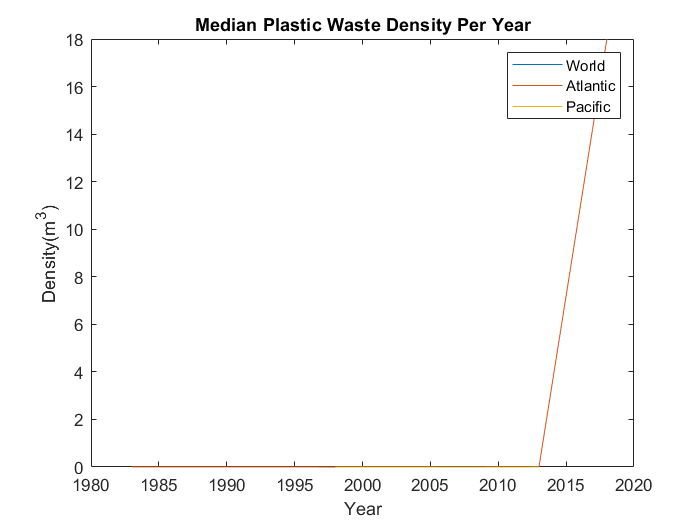

figure(10)
plot(stamps(2:end),medians(:,1))
hold on
plot(stamps(2:end),medians(:,2))
hold on
plot(stamps(2:end),medians(:,3))
title('Median Plastic Waste Density Per Year')
xlabel('Year')
ylabel('Density(m^3)')
legend('World','Atlantic','Pacific')

% The gaps in the geobubbles were the areas where environmentalists 
% did not measure any values for years at a time

## Data Analysis (pollution_density.csv)

We ran density_data based on the density column through the **Regression Learner**. We exported the model with the **lowest RSME** score for the **highest accuracy** and saved it as ‘trainedReg.mat’. The date column was converted from ‘datetime’ to ‘datenum’ since the regression learner can’t read values of the datetime class. We created a new data set with the density values being wiped and the years increased by 20. A new set of density values is generated by the regression learner model and inserted into the new table to predict plastic density 20 years from now.

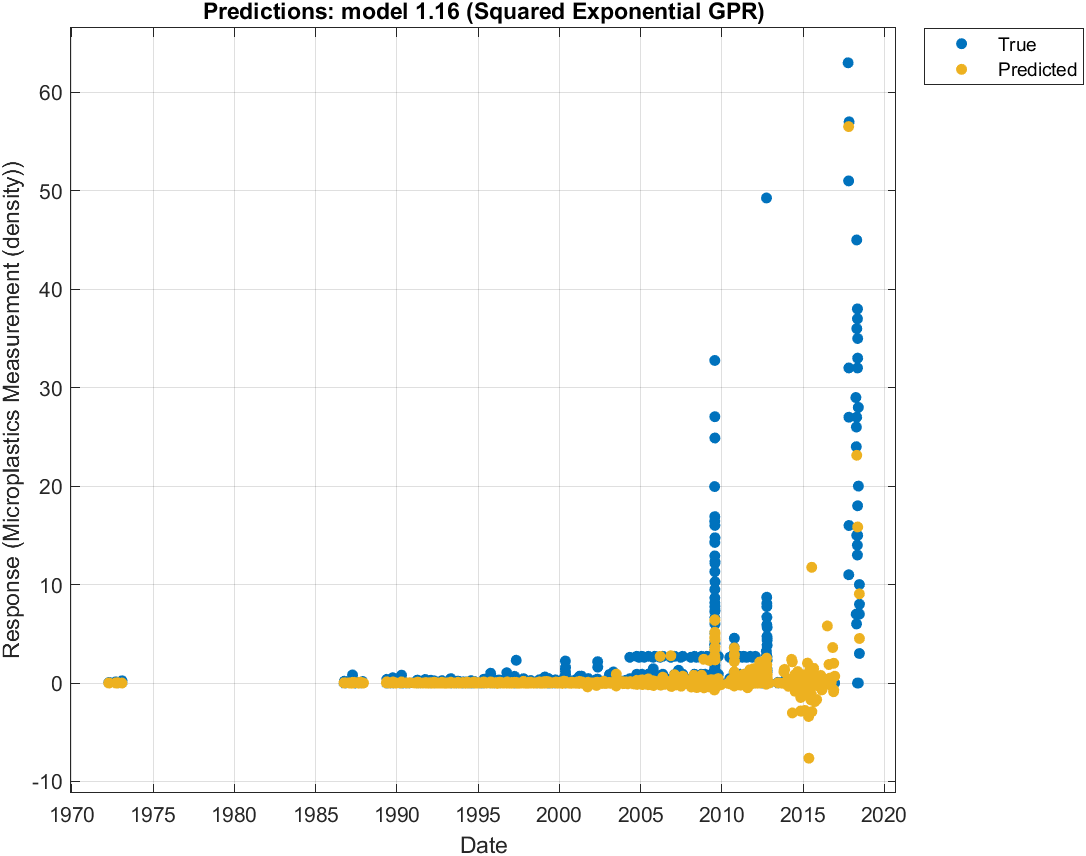

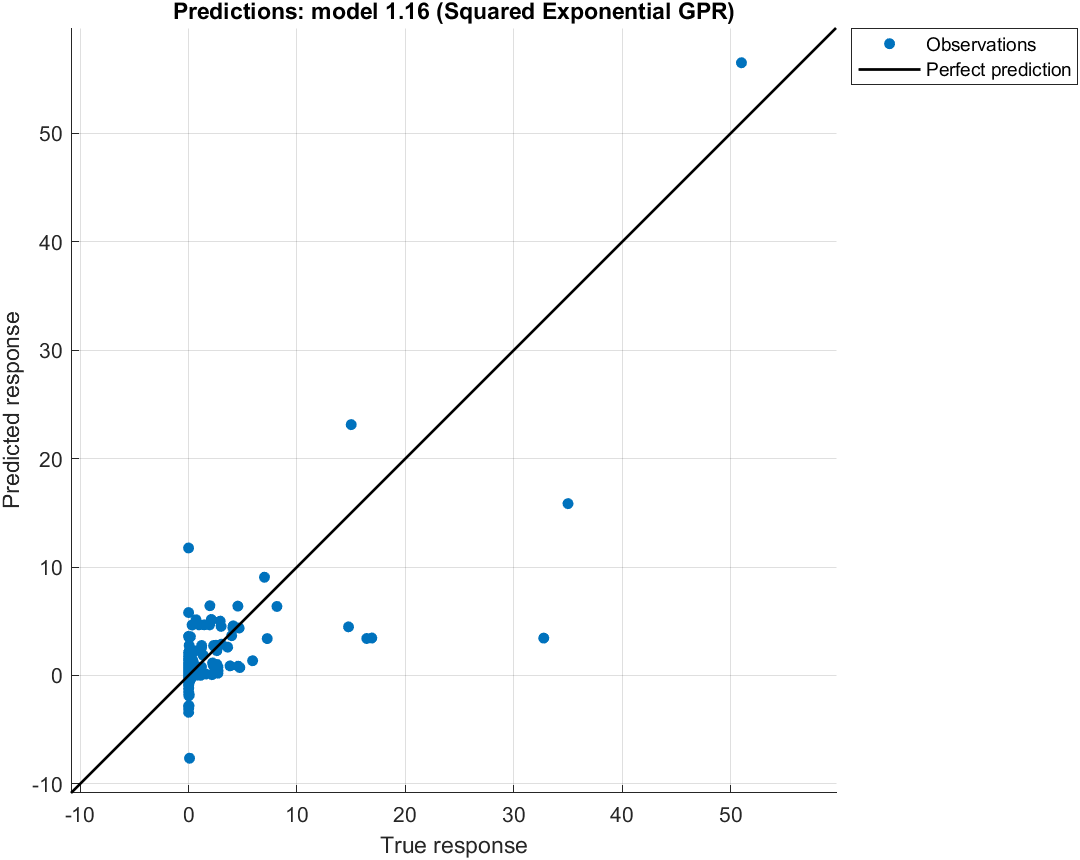

trainedReg = importdata('trainedReg.mat');

% turns 'datetime' into 'datenum'
% turns 'datenum' values into year values
density_data.Date = datenum(density_data.Date) / 365.25;

% new table for integrating machine learning results
density_data_new = density_data;

% wipes out the original density values
[density_data_new.('Microplastics Measurement (density)')(1:height(density_data_new))] = nan;

% increases years to predict data 20 years from now
density_data_new.Date = density_data_new.Date + 20;

head(density_data_new)

ans = 8×7 table
    FID     Date     Latitude    Longitude         Oceans         Microplastics Measurement (density)               Density Class            
    ___    ______    ________    _________    ________________    ___________________________________    ____________________________________

     1     2012.8     18.83       -59.35      "Atlantic Ocean"                    NaN                    Low : 0.0005-0.005 pieces/m³        
     2     2012.8     18.83       -59.35      "Atlantic Ocean"                    NaN                    Medium : 0.005-1 pieces/m³          
     3     2012.8      17.8       -59.43      "Atlantic Ocean"                    NaN                    Medium : 0.005-1 pieces/m³          
     4     2012.8      17.8       -

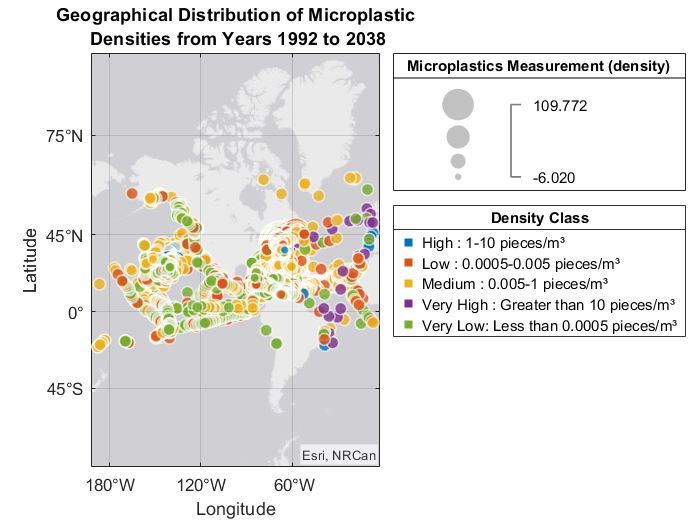

% generates new density values from the machine learning model
yfit = trainedReg.predictFcn(density_data_new);

% inputs the generated values
[density_data_new.('Microplastics Measurement (density)')(1:height(density_data_new))] = yfit;

% final geobubble title is printed with sprintf to show that our 
% model is predicting distribution of microplastics in the future
% (from 1992 to 2038)
figure(11)
geobubble(density_data_new,'Latitude','Longitude', ...
    'SizeVariable','Microplastics Measurement (density)','ColorVariable','Density Class')
name = sprintf("Geographical Distribution of Microplastic\n Densities from Years %.f to %.f", ...
    min(density_data_new.Date), max(density_data_new.Date));
title(name)

## Import the Data (pollution_type.csv)

Below we are importing the data from our pollution_type csv file.

type_data = readtable('pollution_type.csv', 'PreserveVariableNames', true);
head(type_data);

## Scrub the Data (pollution_type.csv)

To make our data set more usable for analysis, we decided to keep only the fields detailing the time, pollution id, pollution type, material id, material type, latitude, longitude, and country. We then removed data points that had unusable values for pollution and material type (having a NULL or other meaningless value). Finally, we created a copy of the data set called typetime.data that had all the unusable values for time removed in case we wanted to look at the correlation of our data with time. Since the **classifcation learner** does not currently have support for the datetime type, we decided to convert our datetime values to its fractional year value.

% removing irrelevant field names
type_data = removevars(type_data,{'OBJECTID','pollution_event_no','Join_Count','TARGET_FID', ...
    'obs_trip_no','pollution_report_no','obs_form_vers','inc_time','inc_dtime','eez_code', ...
    'port_id','activ_id','vatyp_id','stickers_ans','aware_ans','advised_ans','location_other', ...
    'eez_subcode', 'pollution_desc','pollution_qty','Note1','Note2','Note3','Note4','Note5', ...
    'Note6','Note7','Note8','Note9','Note10','Note11','EEZ_Local','ISO_3digit','PACIOCEA'});
head(type_data)

ans = 8×8 table
        inc_date        pollutiontype_id            pollution_type             material_id          material           LAT_1       LONG           Country       
    ________________    ________________    _______________________________    ___________    ____________________    ________    ______    ____________________

                 NaT           71           {'Waste dumped overboard'     }        64         {'Old fishing gear'}    -0.42685    146.49    {'Papua New Guinea'}
    20/04/2010 00:00           72           {'Oil splillages and leakages'}        68         {'Vessel Underway' }     -1.6581    152.68    {'Papua New Guinea'}
    27/05/2010 00:00           71           {'Waste dumped overboar

% removing invalid data points that won't be used
% for the classification learner
logrow = ((type_data.pollutiontype_id > 69 & type_data.pollutiontype_id < 73) | ...
    (type_data.pollutiontype_id == 190)) & (type_data.material_id > 59);
type_data = type_data(logrow,:);
head(type_data)

ans = 8×8 table
        inc_date        pollutiontype_id            pollution_type             material_id          material           LAT_1       LONG           Country       
    ________________    ________________    _______________________________    ___________    ____________________    ________    ______    ____________________

                 NaT           71           {'Waste dumped overboard'     }        64         {'Old fishing gear'}    -0.42685    146.49    {'Papua New Guinea'}
    20/04/2010 00:00           72           {'Oil splillages and leakages'}        68         {'Vessel Underway' }     -1.6581    152.68    {'Papua New Guinea'}
    27/05/2010 00:00           71           {'Waste dumped overboar

% removing points with NaT (not a time) values in a new data set
typetime_data = rmmissing(type_data);

% creating data set for material type analysis
mat_data = type_data((type_data.pollutiontype_id == 71),:);
mattime_data = rmmissing(mat_data);
mattime_data.inc_date = datenum(mattime_data.inc_date) / 365.25;
head(mat_data)

ans = 8×8 table
        inc_date        pollutiontype_id          pollution_type          material_id          material           LAT_1       LONG           Country       
    ________________    ________________    __________________________    ___________    ____________________    ________    ______    ____________________

                 NaT           71           {'Waste dumped overboard'}        64         {'Old fishing gear'}    -0.42685    146.49    {'Papua New Guinea'}
    27/05/2010 00:00           71           {'Waste dumped overboard'}        60         {'Plastics'        }      9.3695    143.49    {'Micronesia'      }
    27/05/2010 00:00           71           {'Waste dumped overboard'}        60       

## Exploratory Data Analysis (pollution_type.csv)

To visualize our raw data after cleaning the data set, we generated pie charts and geographic bubble charts for pollution type and material type.

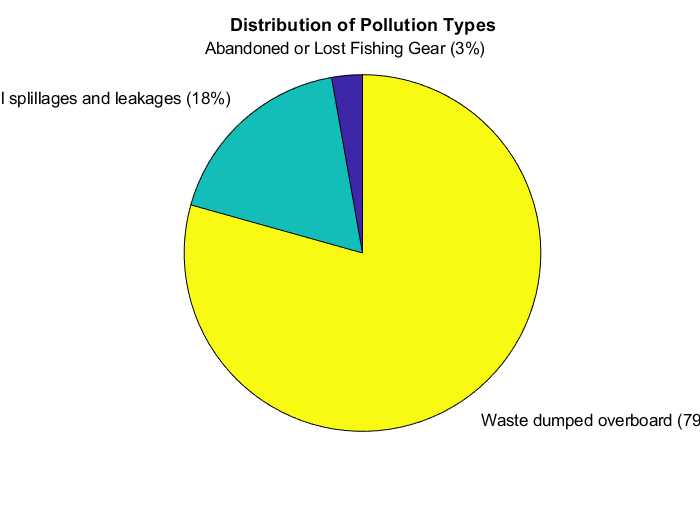

pol_type = categorical(type_data.pollution_type);
mat_type = categorical(mat_data.material);

% pie charts
figure(1)
pie(pol_type);
title('Distribution of Pollution Types')

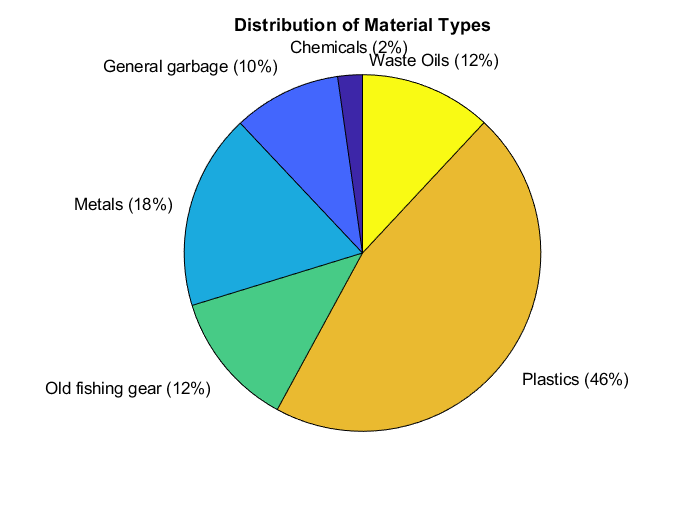

figure(2)
pie(mat_type);
title('Distribution of Material Types')

% The below pie chart is supposed to say
% abandoned or lost fishing gear (3%)
% oil spillages and leakages (18%)
% waste dumped overboard (79%)

% geographical diagrams
figure(3)
geobubble(type_data.LAT_1,type_data.LONG,1,pol_type);

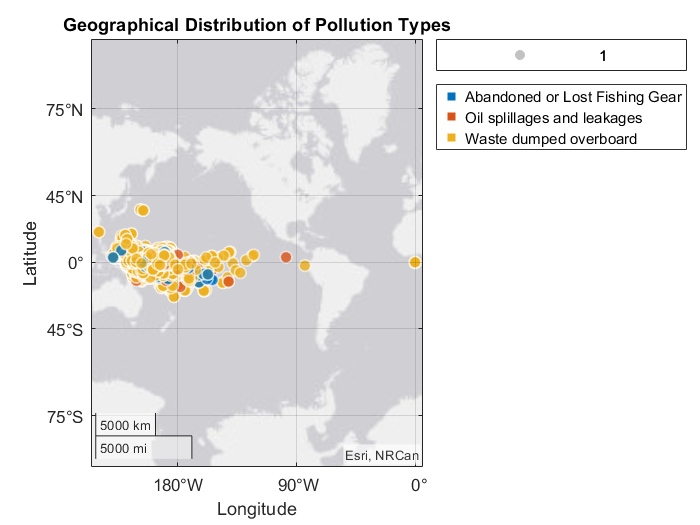

title('Geographical Distribution of Pollution Types')

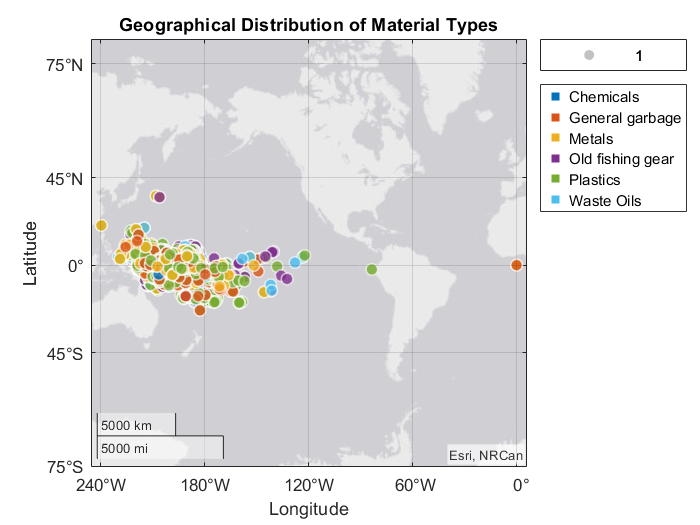

figure(4)
geobubble(mat_data.LAT_1,mat_data.LONG,1,mat_type);
title('Geographical Distribution of Material Types')

## Data Analysis (pollution_type.csv)

After plugging in our cleaned data into the **Classification Learner**, we trained all possible models to find the one with the highest accuracy. We then exported the trained model to predict new data points for future years. 

**However**, for this Classification Learner model, we used pollution material data to predict what country would dispose of that material waste. This means the machine learning program is actually extrapolating the country for each material waste (not what we want), not the material waste for each country (what we want).

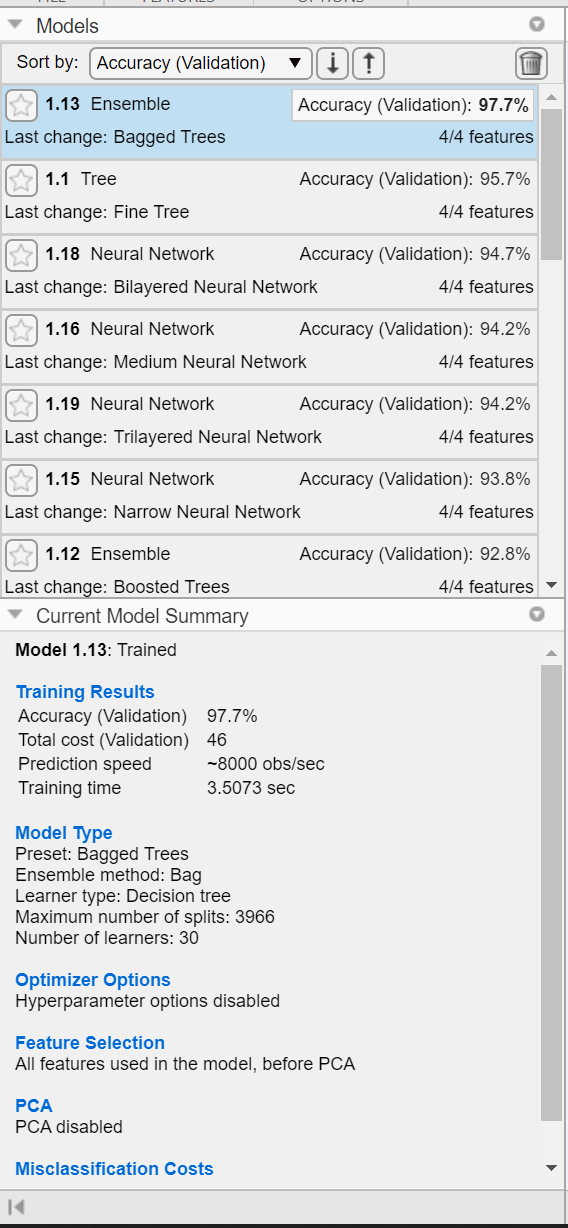

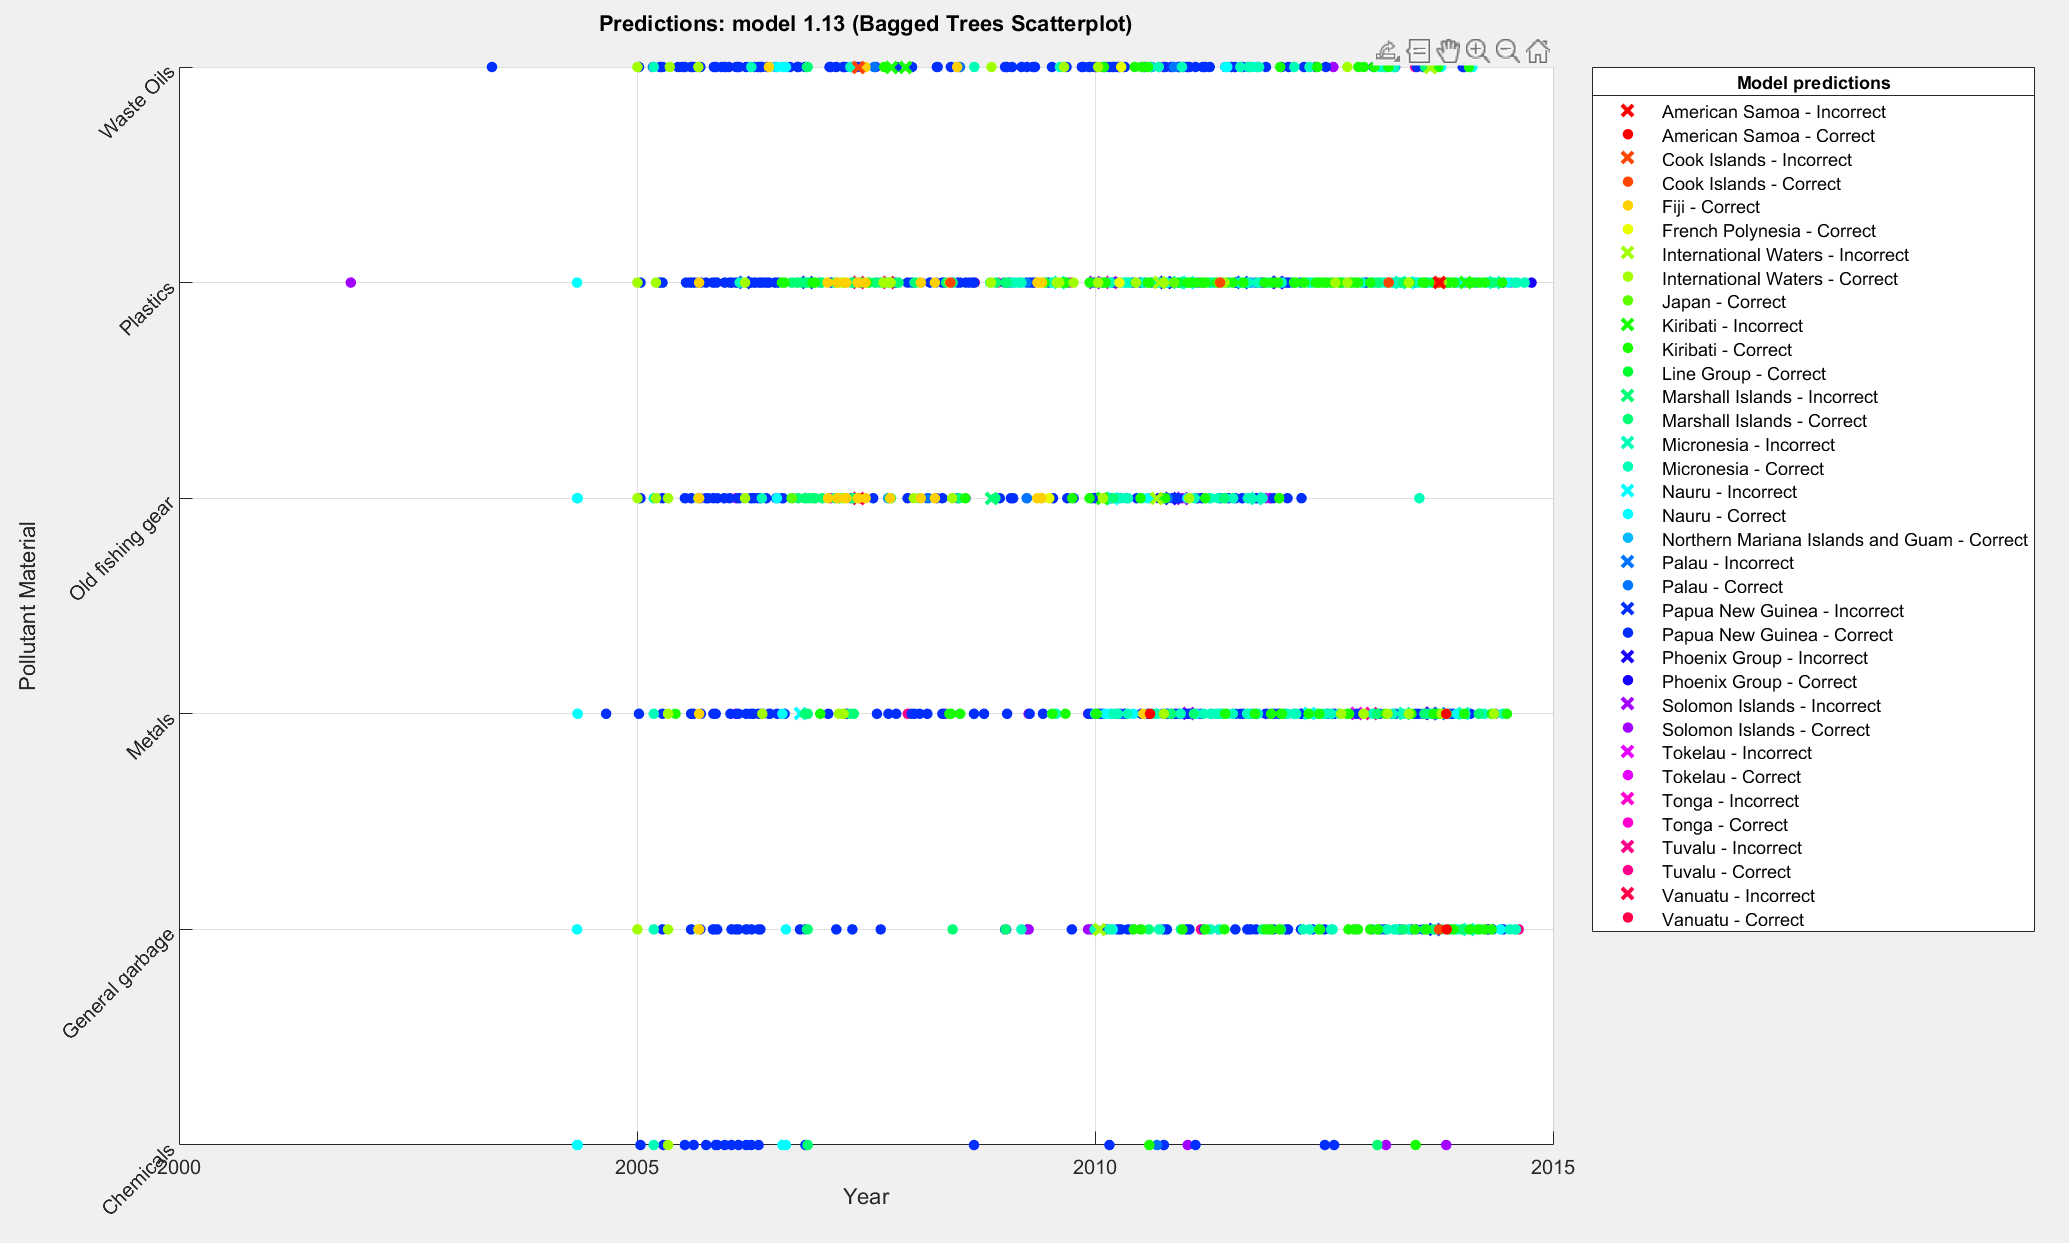

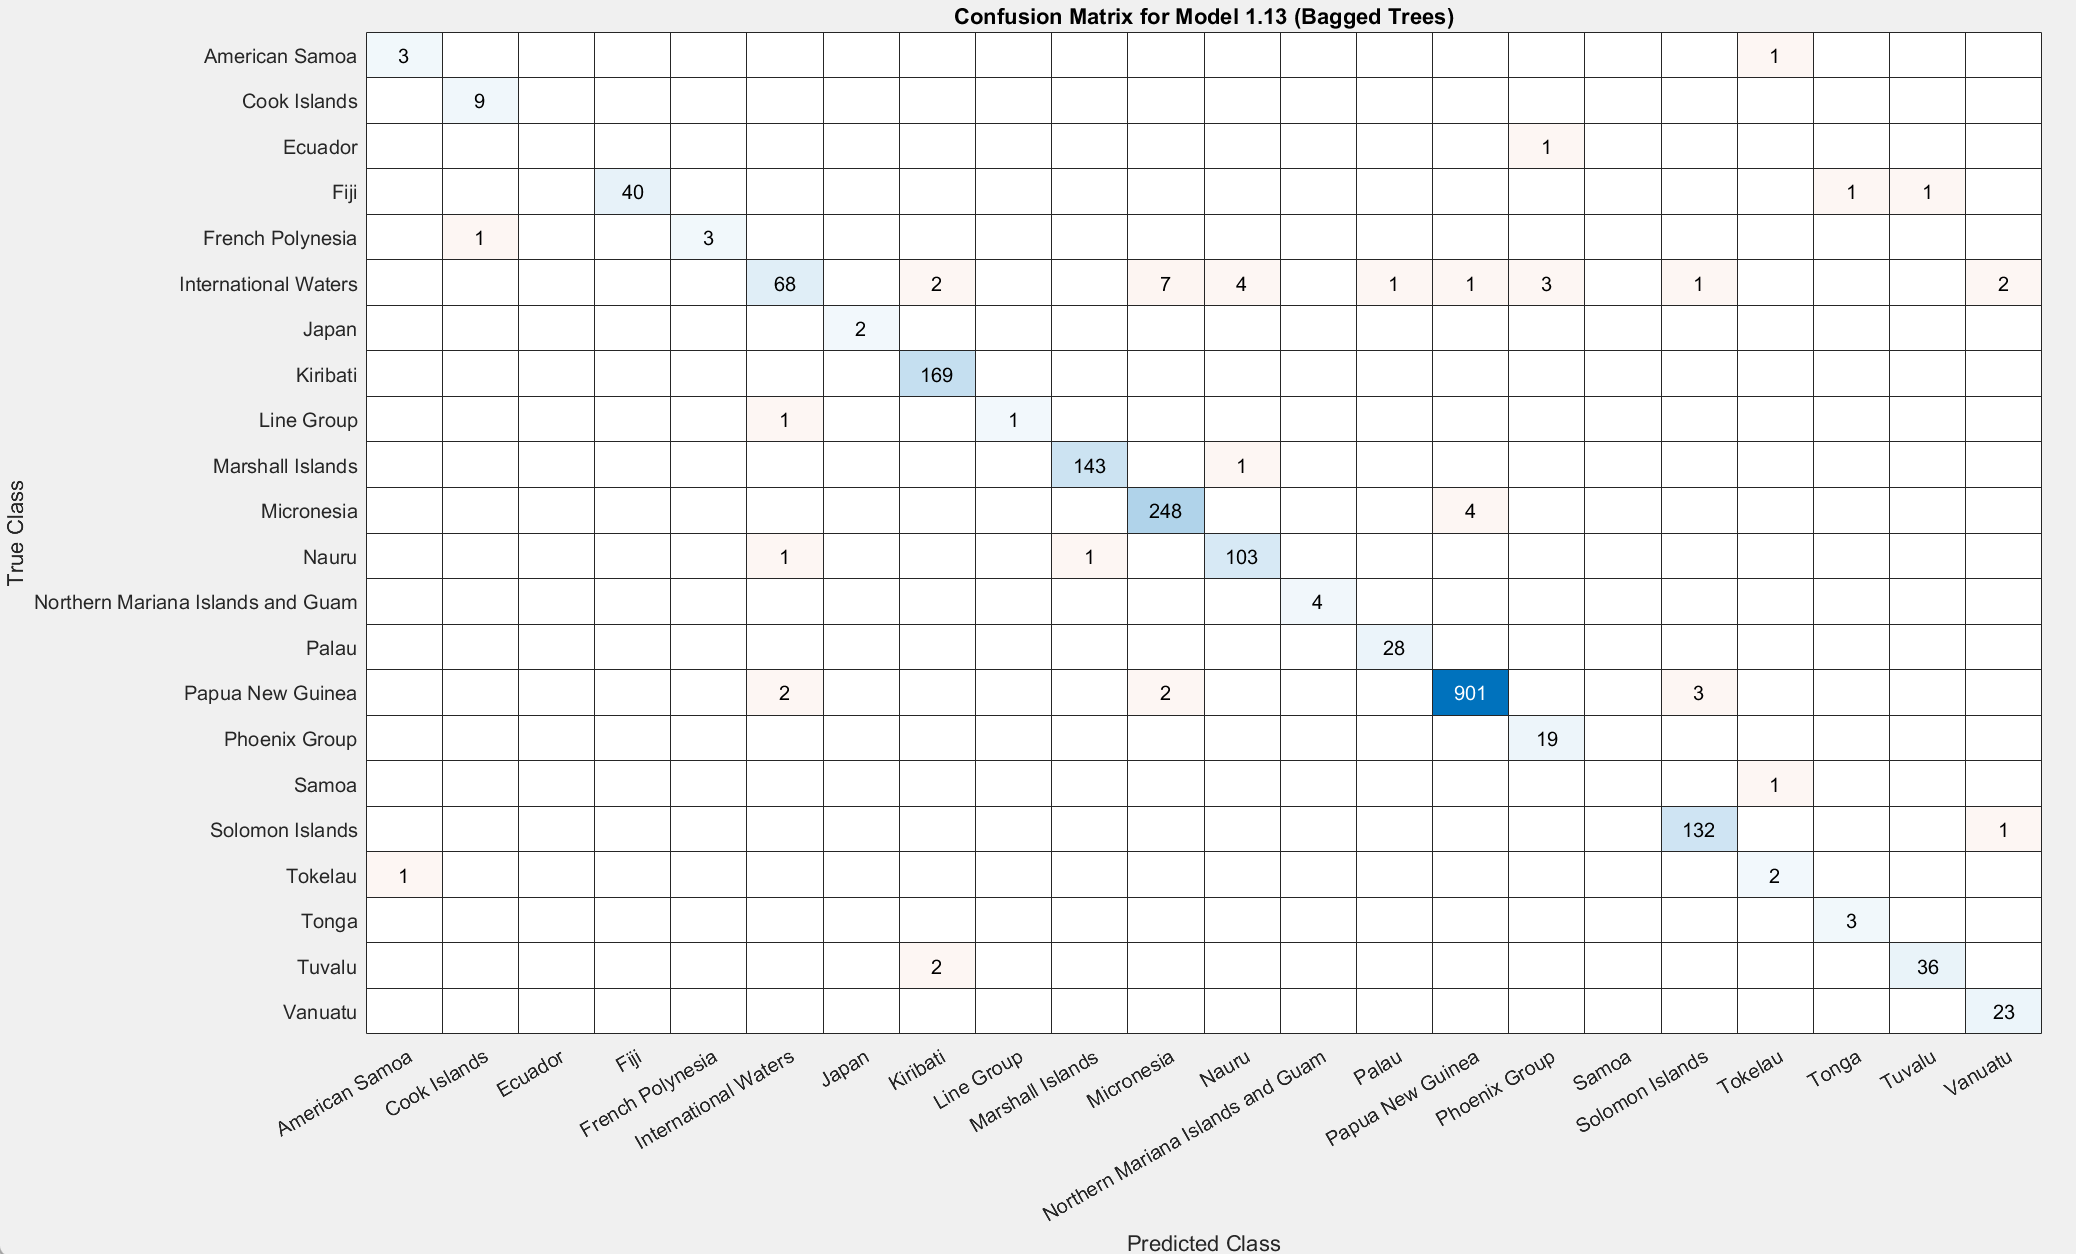

Now, we are showing the information for the models with the **correct Classification Learner**, which will predict each country's most popular type of waste material in the future.

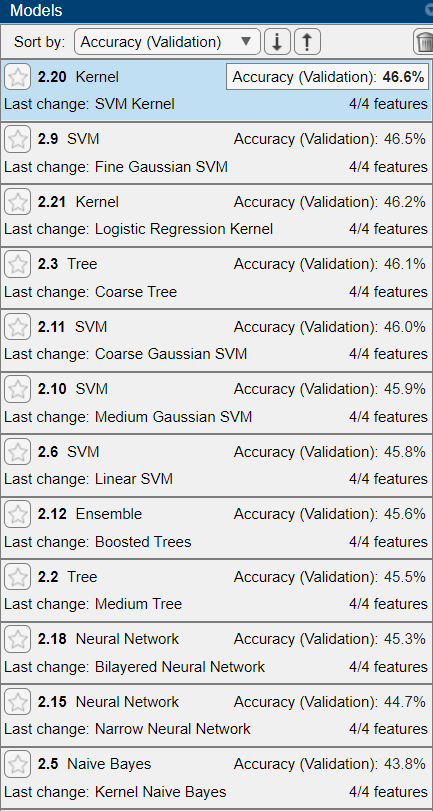

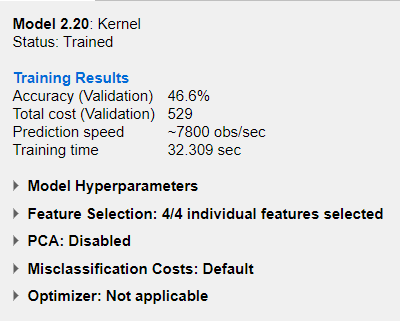

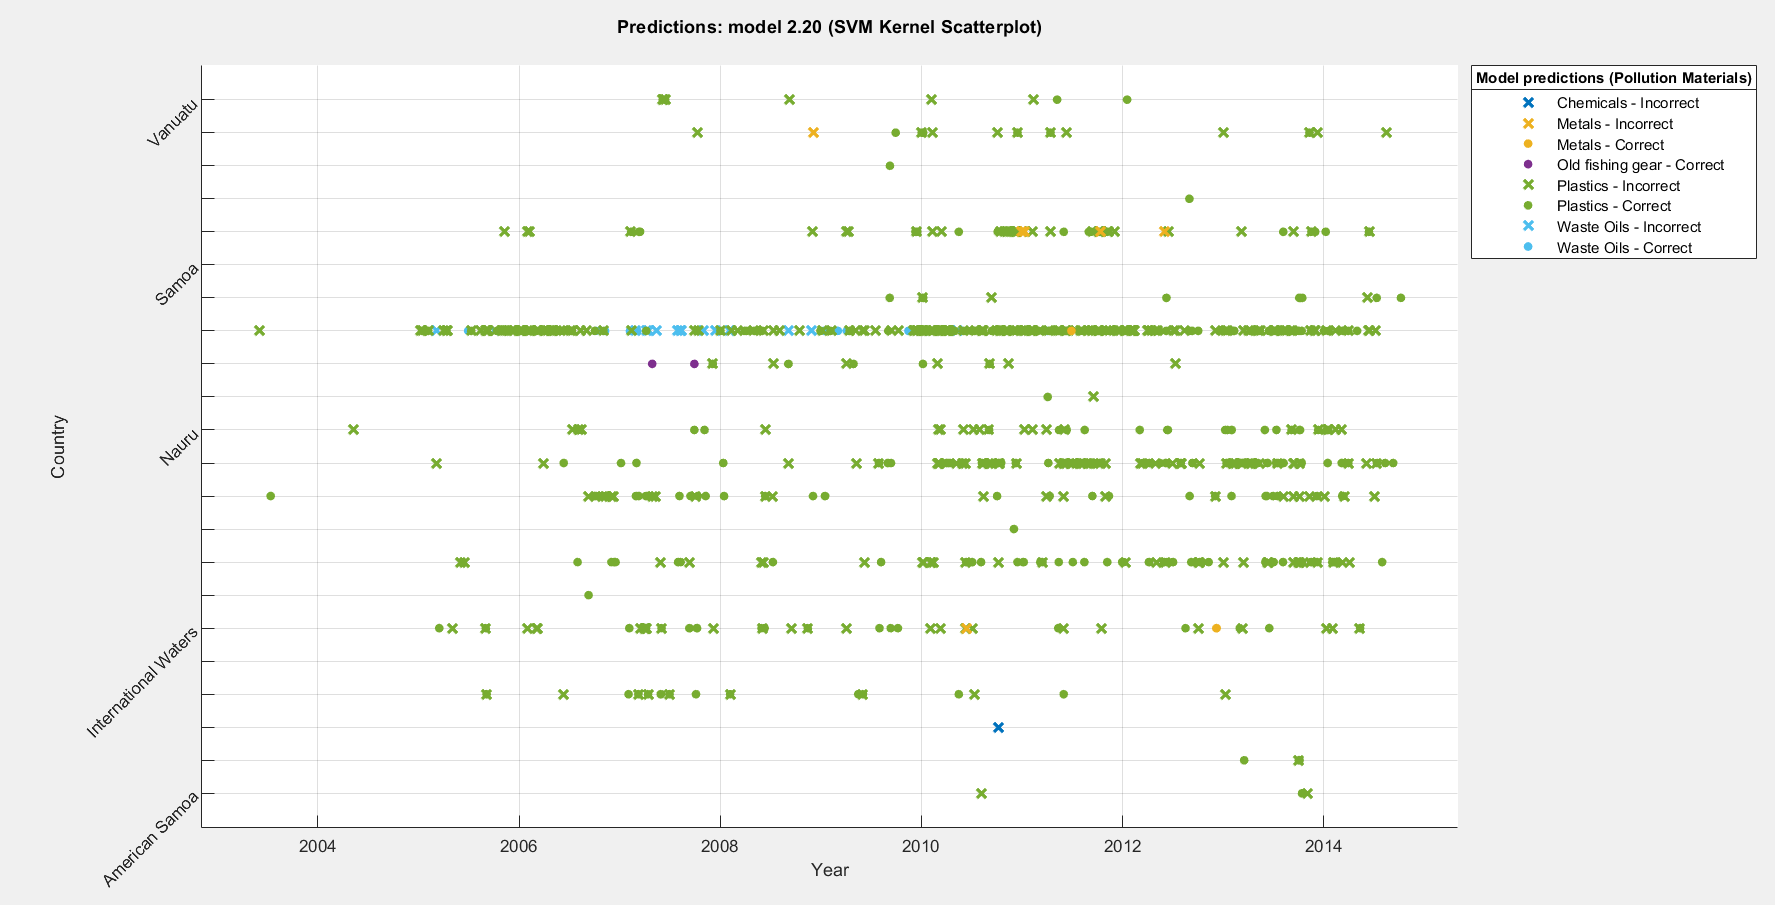

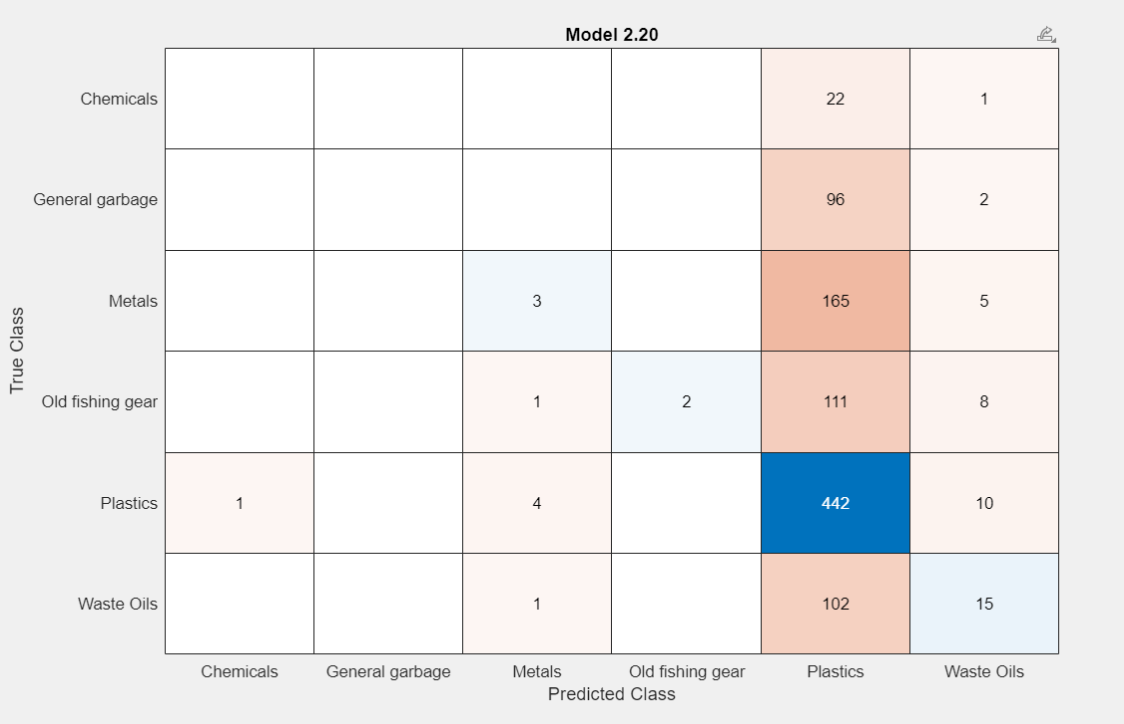

As you can see, the accuracy for this model is low and it also has a weak validation confusion matrix (shown above with a weak diagonal). That is because geographical information (such as longitude and latitude and country name) is **not a good indicator** for a country's most prominent pollution material. Nevertheless, we will proceed with using this exported model to **try to predict future pollution materials** for all the countries in the original data file.

trainedClass = importdata('trainedClass.mat');

% creating a copy of the testing data file and changing
% the years to 20 years into the future for the model to 
% predict. The materials column was deleted in Microsoft
% excel as we couldn't make it NaN here. The new csv file
% with all year information 20 years later and no materials
% was renamed to pred2

pred_mattime_data = mattime_data;
pred_mattime_data.inc_date = pred_mattime_data.inc_date + 20;
writetable(pred_mattime_data,'pred.csv');

pred2 = readtable('pred2');
head(pred2)

ans = 8×8 table
    inc_date    pollutiontype_id          pollution_type          material_id    material     LAT_1      LONG           Country       
    ________    ________________    __________________________    ___________    ________    _______    ______    ____________________

     2030.4            71           {'Waste dumped overboard'}        60           NaN        9.3695    143.49    {'Micronesia'      }
     2030.4            71           {'Waste dumped overboard'}        60           NaN        9.3695    143.49    {'Micronesia'      }
     2030.3            71           {'Waste dumped overboard'}        62           NaN        -3.253    156.24    {'Papua New Guinea'}
     2030.3            71           

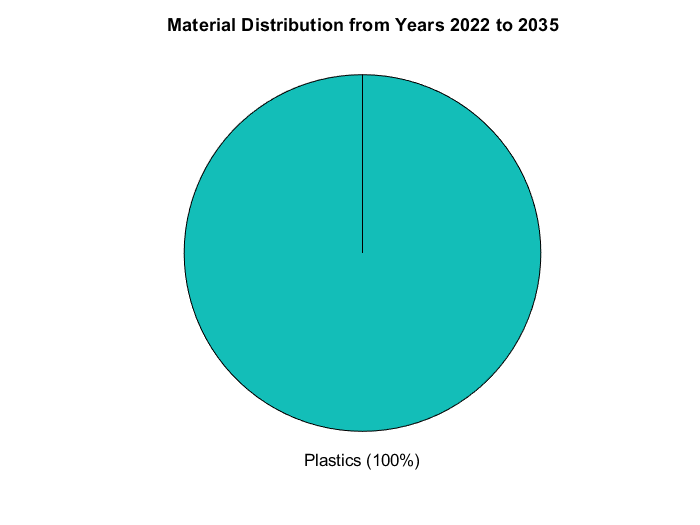

% using our exported model to predict 
% material type for each country
% 20 years into the future
mat_guess = trainedClass.predictFcn(pred2);
pred2.material = mat_guess;
pred_mat_type = categorical(pred2.material);

% pie charts
% years from the title are printed with sprintf
% to show that we're predicting pollution material
% for the future (which we got via our machine 
% learning model from above steps)
figure(5)
pie(pred_mat_type);
name = sprintf("Material Distribution from Years %.f to %.0f",min(pred2.inc_date),max(pred2.inc_date));
title(name)

figure(6)
geobubble(pred2.LAT_1,pred2.LONG,1,pred_mat_type);

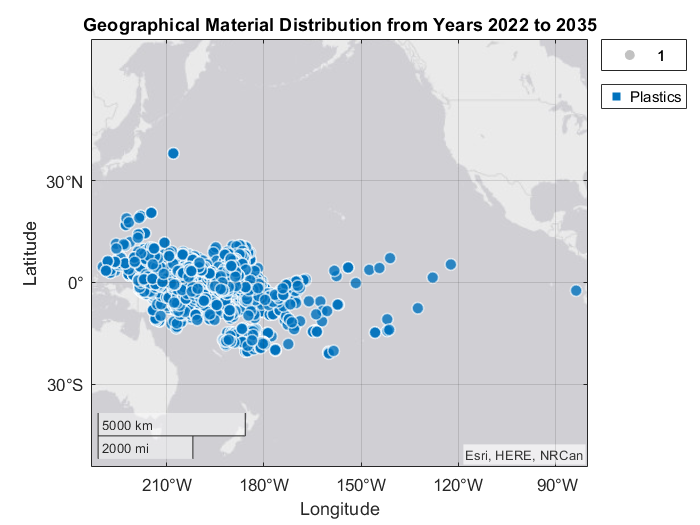

name2 = strcat("Geographical ", name);
title(name2)

## Conclusions (for both data sets)

In our project proposal, we said we wanted to do two things: identify the areas across the world that will be most populated with pollution in the future through the use of the Regression Learner (1) and identify the specific type of pollution that will become most prominent in the future through the use of the Classification Learner (2). 

Before we used the Regression Learner, this was the geobubble for the microplastic distribution from 1978 to 2018 (eight graphs for five-year intervals). 

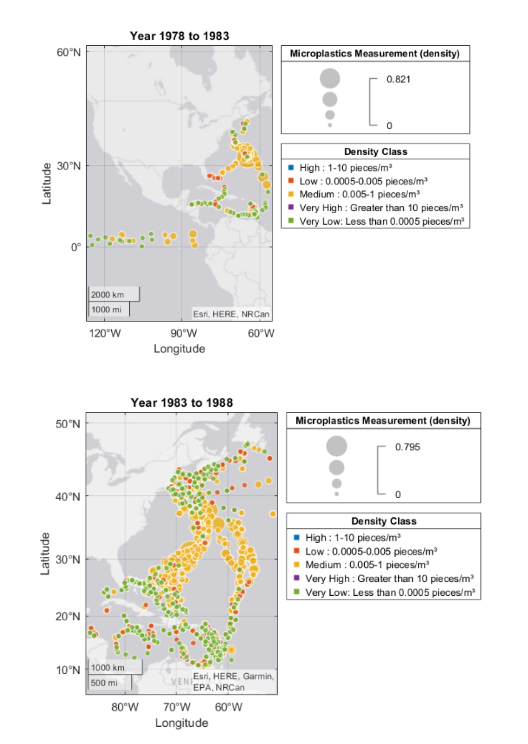

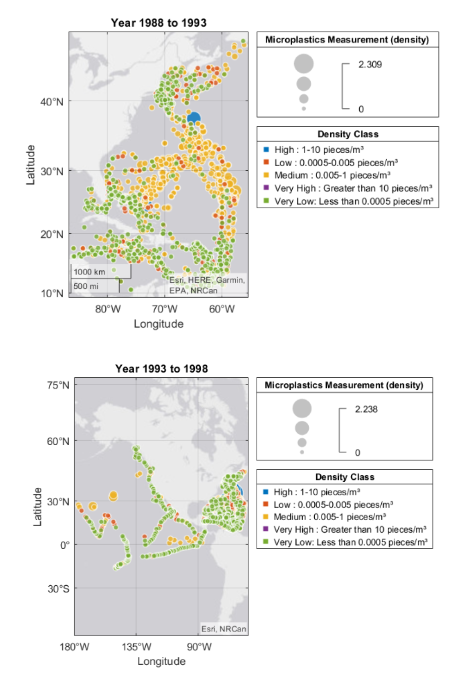

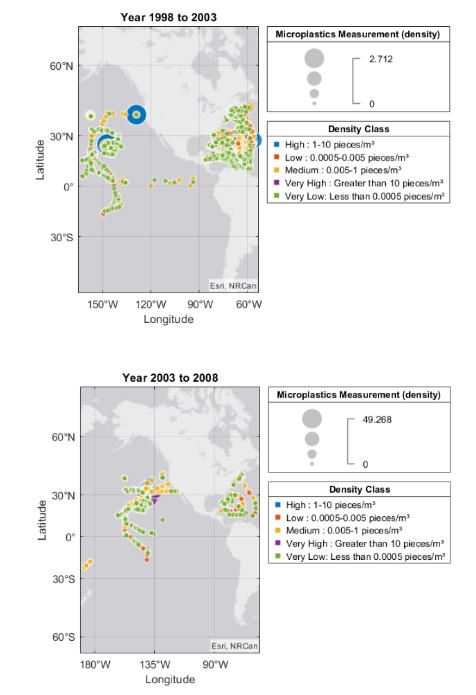

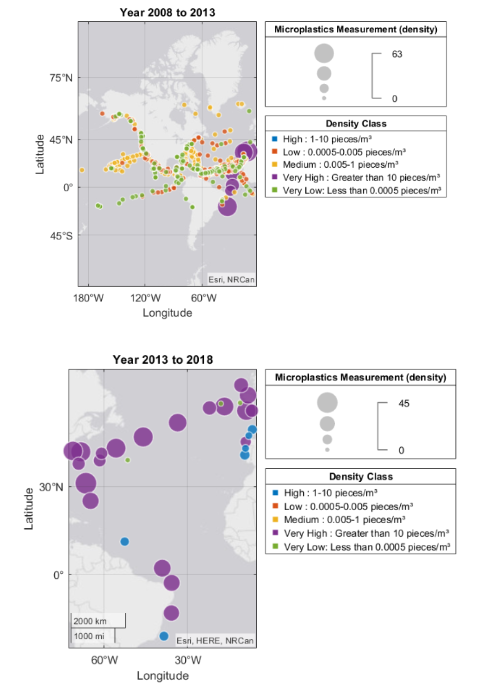

We used all this training data to export a regression learner model that can predict geographic distribution of microplastics densities in the future. To do this, we created another data set with all the same information as before, except with the microplastic densities erased (for the model to predict) and all previous time information moved up 20 years. Having done this, this is the predicted geographic distribution of microplastics densities from 1992 to 2038: 

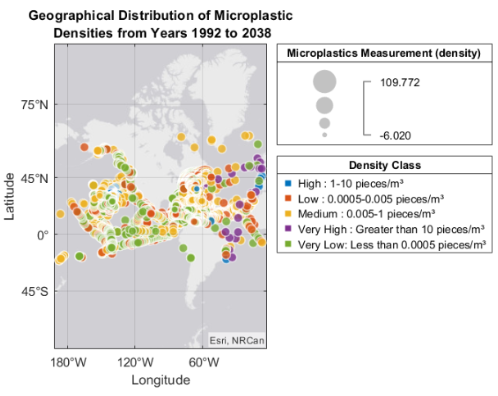

Looking at this, it is clear that the most densely polluted areas (purple) in the future will be around the Atlantic Ocean (the ocean east of North America and South America). **This means that current and future ocean cleanup efforts should be focused on the Atlantic Ocean first.**

Moving onto the second purpose stated in our proposal (identifying the specific type of pollution that will become most prominent in the future through the use of the Classification Learner), this is the original distribution of pollution types from 2002 to 2015 according to our data set:

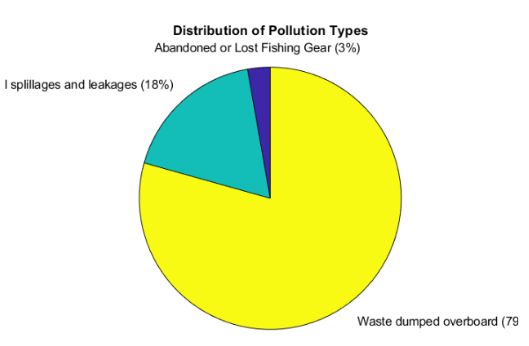

*For interpretation purposes, 3% is Abandoned or Lost Fishing Gear, 18% is Oil spillages and leakages, and 79% is waste dumped overboard.*

Furthermore, this is the distribution of material types for those pollutants from 2002 to 2015.

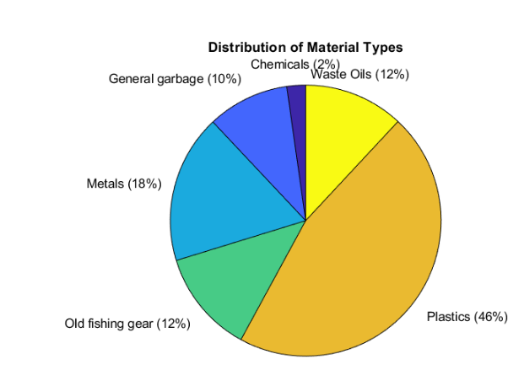

With the trends analyzed by the classification learner (which had a poor accuracy and weak validation confusion matrix), the exported model predicted that in 20 years (from 2022 to 2035), the material distribution of pollution will be **100% plastic.** 

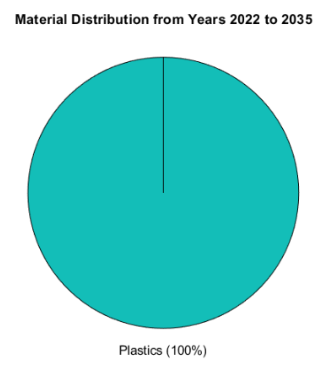

One reason why the above pie chart has just plastics and not other materials as future ocean pollutants is because with a weak/inaccurate exported model (**46.6% accuracy**), it anticpates that an increase in plastic distribution over time would mean that eventually, **all pollutants will be plastics**. Nevertheless, we can still draw valid conclusions from the above prediction. 

That valid conclusion is, **with each passing day, plastics become a more common pollutant in our oceans.** For that reason, current and future ocean cleanup efforts** should prioritize cleaning up plastics first over all other types of pollutants (metals, oil, chemicals). **Additionally, knowing that plastics will be the most common ocean pollutant in the future**, we should create policies today to limit the amount of plastic that ends up in our oceans. **

After all, according to our models, our future waters will become a **sea of plastics**, so it is our job to prioritize **cleaning plastics first** over all other pollutants. Referring back to our previous model, when cleaning plastics in our oceans, **we should start at the Atlantic Ocean**, where it is **most concentrated**, over any other location.